% AM Code

% INSTRUCTIONS
% a. Modulating signal (show graph) what signal to use
% b. Modulate the signal (show graph)
    % a. Use m = 0.25, 0.5, 0.75, 1
% c. Add white Gaussian noise
    % a. Use SNR = 0dB, 2dB, 5dB, 10dB, -2dB, -5dB, -10dB for ALL RESULTS FROM "b"
% d. Demodulate all the signals with different m and SNR
% e. Recover the received signal (show graph and play audio)

a. Modulating signal (show graph) 

[y, Fs]= audioread("New-Recording.wav");

Error using audioread>readaudio
The filename specified was not found in the MATLAB path.

Error in audioread (line 160)
    [y, Fs] = readaudio (filename, range, datatype);

sound(y, Fs)

Fc= Fs/2;

plot(y); grid on; title('Modulating Signal')
% audioread for the message signal = modulating signal 

b. Modulate the signal 

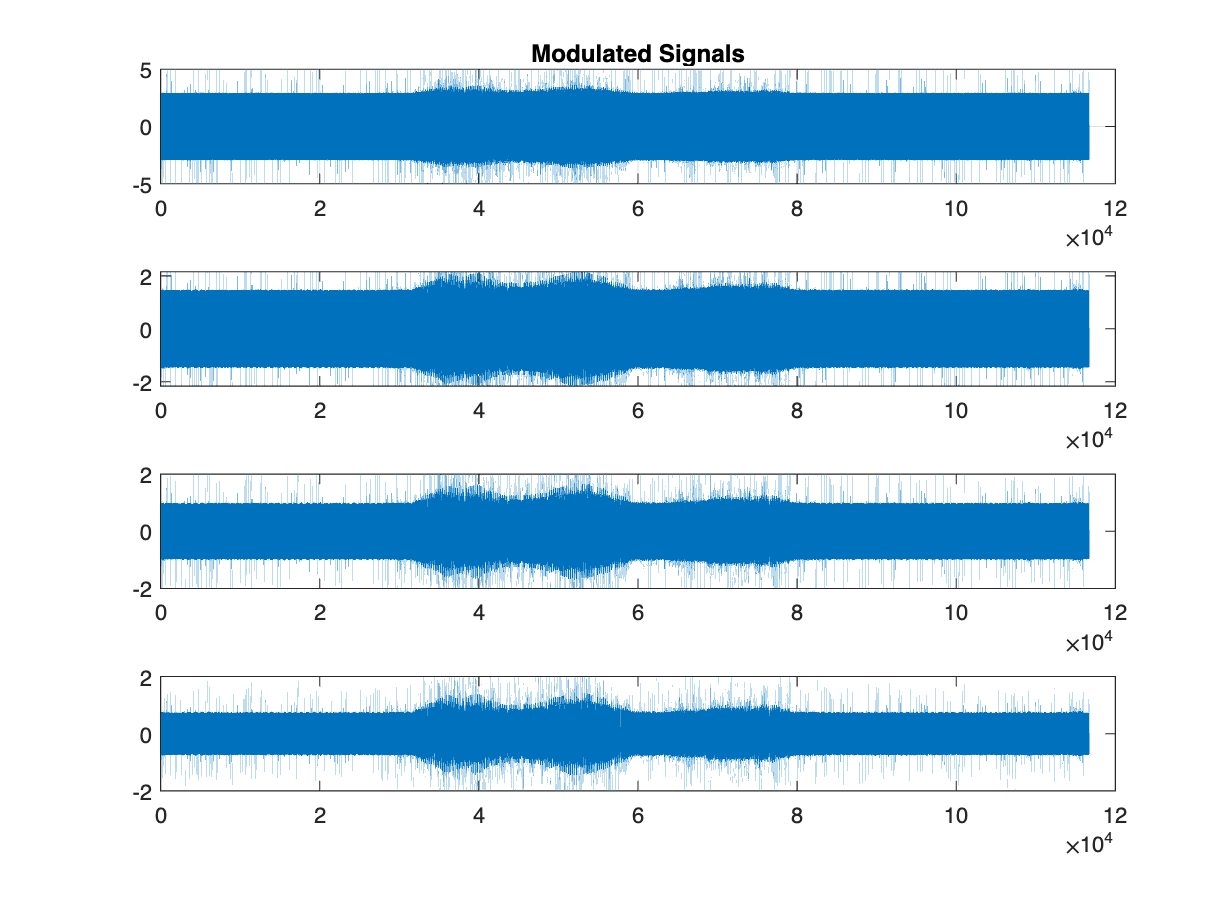

m1= 0.25;
m2= 0.5;
m3= 0.75;
m4= 1;

%Setting the carrier amplitude
Ac1= max(y)/m1;
Ac2= max(y)/m2; 
Ac3= max(y)/m3; 
Ac4= max(y)/m4; 

%Modulating the signals
y_ammod1= ammod(y,Fc, Fs, 0, Ac1);
y_ammod2= ammod(y,Fc, Fs, 0, Ac2);
y_ammod3= ammod(y,Fc, Fs, 0, Ac3);
y_ammod4= ammod(y,Fc, Fs, 0, Ac4);

figure (1);
subplot(411); plot(y_ammod1); grid on; title ('Modulated Signals');
subplot(412); plot(y_ammod2);
subplot(413); plot(y_ammod3);
subplot(414); plot(y_ammod4);

c. Add white Gaussian noise 

snr1= 0;
snr2= 2;
snr3= 5;
snr4= 10;
snr5= -2;
snr6= -5;
snr7= -10;

% For all snr=0:
noise01 = awgn(y_ammod1,snr1);
noise02 = awgn(y_ammod2,snr1);
noise03 = awgn(y_ammod3,snr1);
noise04 = awgn(y_ammod4,snr1);

% For all snr=2:
noise11 = awgn(y_ammod1,snr2);
noise12 = awgn(y_ammod2,snr2);
noise13 = awgn(y_ammod3,snr2);
noise14 = awgn(y_ammod4,snr2);

% For all snr=5:
noise21 = awgn(y_ammod1,snr3);
noise22 = awgn(y_ammod2,snr3);
noise23 = awgn(y_ammod3,snr3);
noise24 = awgn(y_ammod4,snr3);

%For all snr=10:
noise31 = awgn(y_ammod1,snr4);
noise32 = awgn(y_ammod2,snr4);
noise33 = awgn(y_ammod3,snr4);
noise34 = awgn(y_ammod4,snr4);

%For all snr=-2:
noise41 = awgn(y_ammod1,snr5);
noise42 = awgn(y_ammod2,snr5);
noise43 = awgn(y_ammod3,snr5);
noise44 = awgn(y_ammod4,snr5);

%For all snr= -5:
noise51 = awgn(y_ammod1,snr6);
noise52 = awgn(y_ammod2,snr6);
noise53 = awgn(y_ammod3,snr6);
noise54 = awgn(y_ammod4,snr6);

%For all snr= -10:
noise61 = awgn(y_ammod1,snr7);
noise62 = awgn(y_ammod2,snr7);
noise63 = awgn(y_ammod3,snr7);
noise64 = awgn(y_ammod4,snr7);


d. Demodulate all the signals with different m and snr

% demodulated signal with noise
demod01=amdemod(noise01, Fc, Fs+1);
demod02=amdemod(noise02, Fc, Fs+1);
demod03=amdemod(noise03, Fc, Fs+1);
demod04=amdemod(noise04, Fc, Fs+1);

demod11=amdemod(noise11, Fc, Fs+1);
demod12=amdemod(noise12, Fc, Fs+1);
demod13=amdemod(noise13, Fc, Fs+1);
demod14=amdemod(noise14, Fc, Fs+1);

demod21=amdemod(noise21, Fc, Fs+1);
demod22=amdemod(noise22, Fc, Fs+1);
demod23=amdemod(noise23, Fc, Fs+1);
demod24=amdemod(noise24, Fc, Fs+1);

demod31=amdemod(noise31, Fc, Fs+1);
demod32=amdemod(noise32, Fc, Fs+1);
demod33=amdemod(noise33, Fc, Fs+1);
demod34=amdemod(noise34, Fc, Fs+1);

demod41=amdemod(noise41, Fc, Fs+1);
demod42=amdemod(noise42, Fc, Fs+1);
demod43=amdemod(noise43, Fc, Fs+1);
demod44=amdemod(noise44, Fc, Fs+1);

demod51=amdemod(noise51, Fc, Fs+1);
demod52=amdemod(noise52, Fc, Fs+1);
demod53=amdemod(noise53, Fc, Fs+1);
demod54=amdemod(noise54, Fc, Fs+1);

demod61=amdemod(noise61, Fc, Fs+1);
demod62=amdemod(noise62, Fc, Fs+1);
demod63=amdemod(noise63, Fc, Fs+1);
demod64=amdemod(noise64, Fc, Fs+1);

e. Recover the received signal (show graph and play audio)

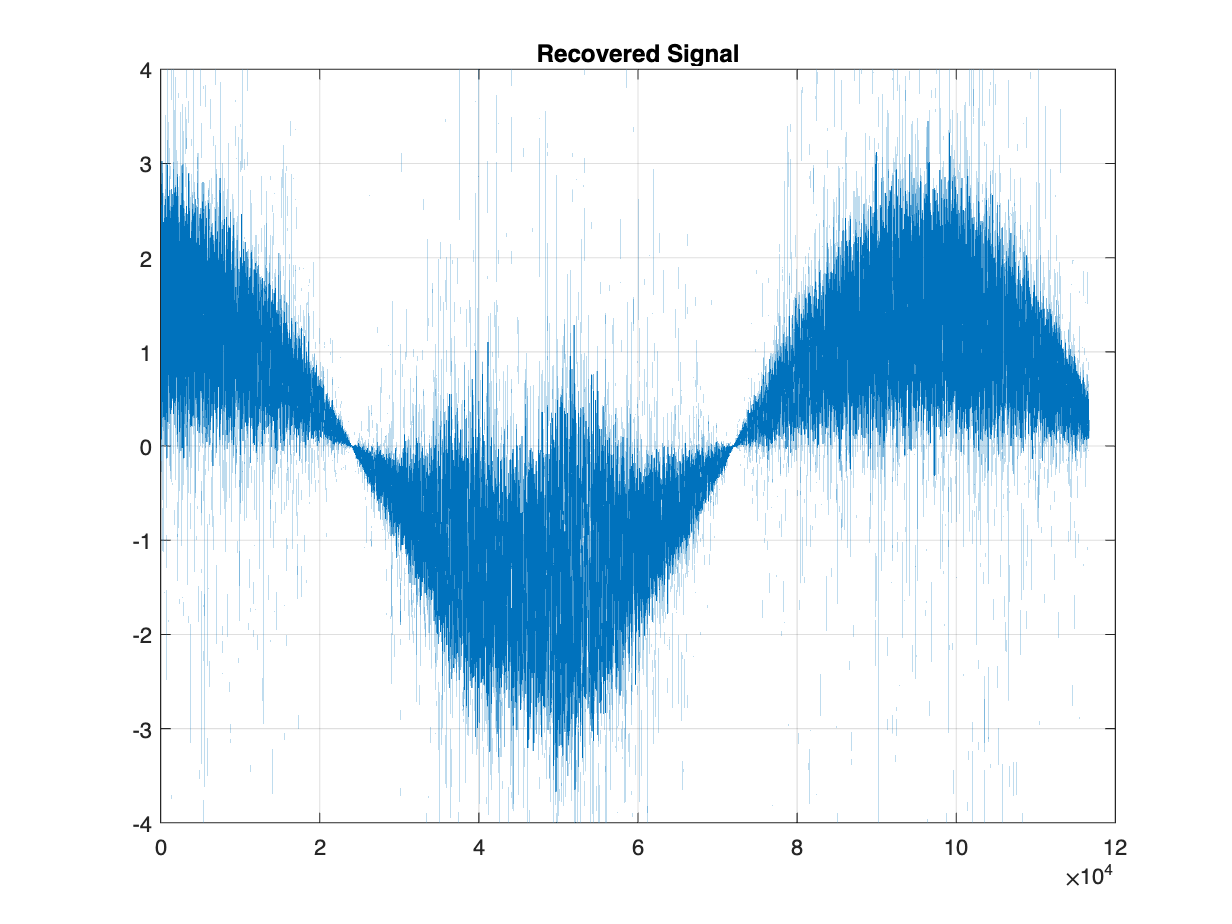

% Demodulated signal is too noisy; hence the application of a filter
% Chosen signal to recover is the most ideal: modulation index of 1 with
% the highest snr. 

% demodulated signal with filter 
[num,den] = butter(10,1.2*Fc/Fs);
filtereddemod=amdemod(noise34, Fc, Fs+1, 0, 0, num, den);

figure (3);
plot(filtereddemod); grid on; title ('Recovered Signal');

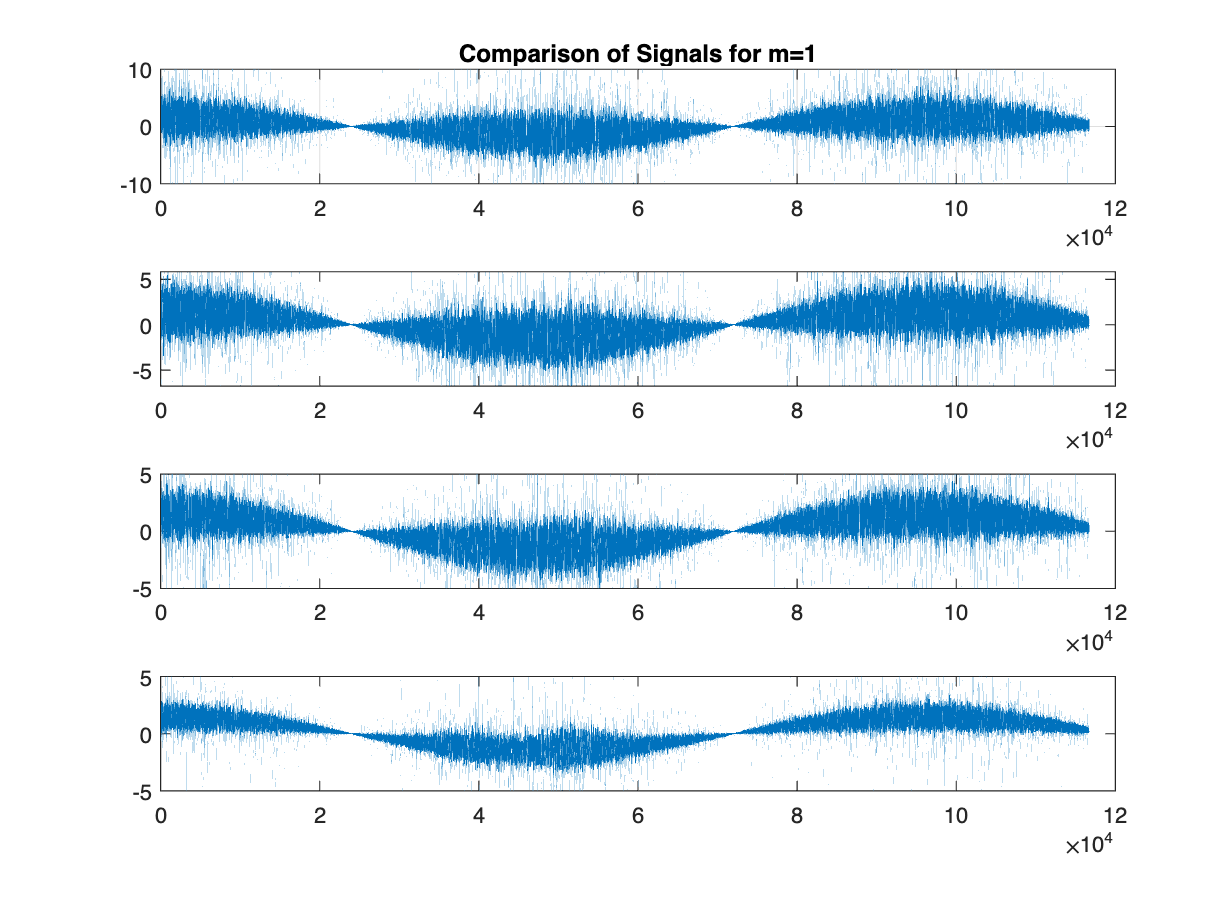


sound(filtereddemod, Fs) % ideal signal to be received as it has 100% modulation, with the highest snr of 10dB. 

%For comparison to other signals with a modulation index 1; 
filtereddemod1=amdemod(noise04, Fc, Fs+1, 0, 0, num, den);
filtereddemod2=amdemod(noise14, Fc, Fs+1, 0, 0, num, den);
filtereddemod3=amdemod(noise24, Fc, Fs+1, 0, 0, num, den);
filtereddemod4=amdemod(noise34, Fc, Fs+1, 0, 0, num, den);

%For comparison to other signals with the highest snr (10dB); 
filtereddemoda=amdemod(noise31, Fc, Fs+1, 0, 0, num, den);
filtereddemodb=amdemod(noise32, Fc, Fs+1, 0, 0, num, den);
filtereddemodc=amdemod(noise33, Fc, Fs+1, 0, 0, num, den);
filtereddemodd=amdemod(noise34, Fc, Fs+1, 0, 0, num, den);

figure (4);
subplot(411); plot(filtereddemod1); grid on; title ('Comparison of Signals for m=1');
subplot(412); plot(filtereddemod2);
subplot(413); plot(filtereddemod3);
subplot(414); plot(filtereddemod4);

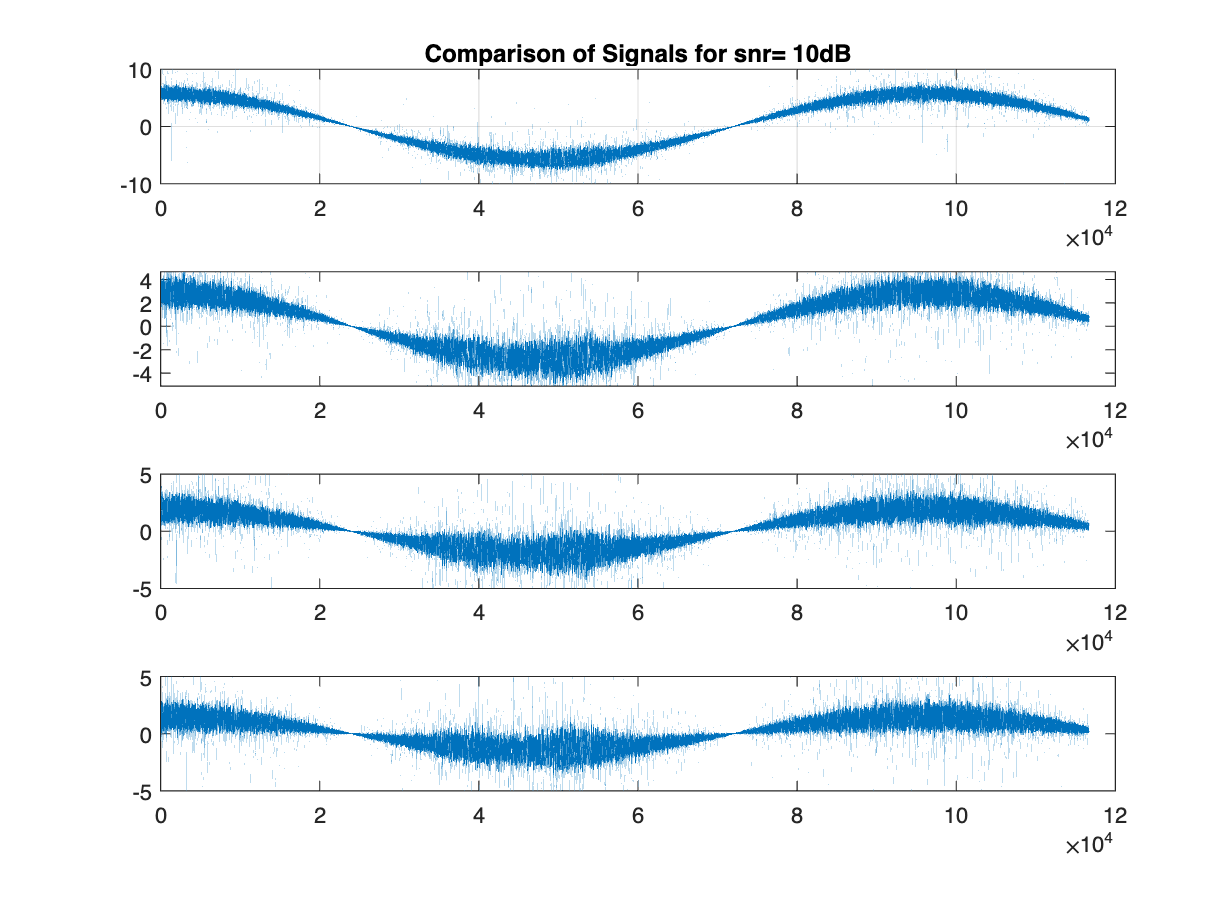


figure (5);
subplot(411); plot(filtereddemoda); grid on; title ('Comparison of Signals for snr= 10dB');
subplot(412); plot(filtereddemodb);
subplot(413); plot(filtereddemodc);
subplot(414); plot(filtereddemodd);

Additional: every other signal sound test:

filtereddemoda1=amdemod(noise11, Fc, Fs+1, 0, 0, num, den);
filtereddemoda2=amdemod(noise12, Fc, Fs+1, 0, 0, num, den);
filtereddemoda3=amdemod(noise13, Fc, Fs+1, 0, 0, num, den);
filtereddemoda4=amdemod(noise14, Fc, Fs+1, 0, 0, num, den);

filtereddemoda6=amdemod(noise21, Fc, Fs+1, 0, 0, num, den);
filtereddemoda7=amdemod(noise22, Fc, Fs+1, 0, 0, num, den);
filtereddemoda8=amdemod(noise23, Fc, Fs+1, 0, 0, num, den);
filtereddemoda9=amdemod(noise24, Fc, Fs+1, 0, 0, num, den);

filtereddemoda10=amdemod(noise41, Fc, Fs+1, 0, 0, num, den);
filtereddemoda11=amdemod(noise42, Fc, Fs+1, 0, 0, num, den);
filtereddemoda12=amdemod(noise43, Fc, Fs+1, 0, 0, num, den);
filtereddemoda13=amdemod(noise44, Fc, Fs+1, 0, 0, num, den);

filtereddemoda14=amdemod(noise51, Fc, Fs+1, 0, 0, num, den);
filtereddemoda15=amdemod(noise52, Fc, Fs+1, 0, 0, num, den);
filtereddemoda16=amdemod(noise53, Fc, Fs+1, 0, 0, num, den);
filtereddemoda17=amdemod(noise54, Fc, Fs+1, 0, 0, num, den);

filtereddemoda18=amdemod(noise61, Fc, Fs+1, 0, 0, num, den);
filtereddemoda19=amdemod(noise62, Fc, Fs+1, 0, 0, num, den);
filtereddemoda20=amdemod(noise63, Fc, Fs+1, 0, 0, num, den);
filtereddemoda21=amdemod(noise64, Fc, Fs+1, 0, 0, num, den);

sound(filtereddemoda21, Fs) % edit with chosen signal for sound test.

Additional: Trial Amplitude modulation with a higher signal-to-noise ratio to modulation index 1. 

snr1a= 50;
noise_a = awgn(y_ammod4,snr1a);
demod_filteredA=amdemod(noise_a, Fc, Fs+1, 0, 0, num, den);
sound(demod_filteredA, Fs)